# **Tema 3: Integración numérica en el plano**

## **EJS HOJA DE PROBLEMAS:**

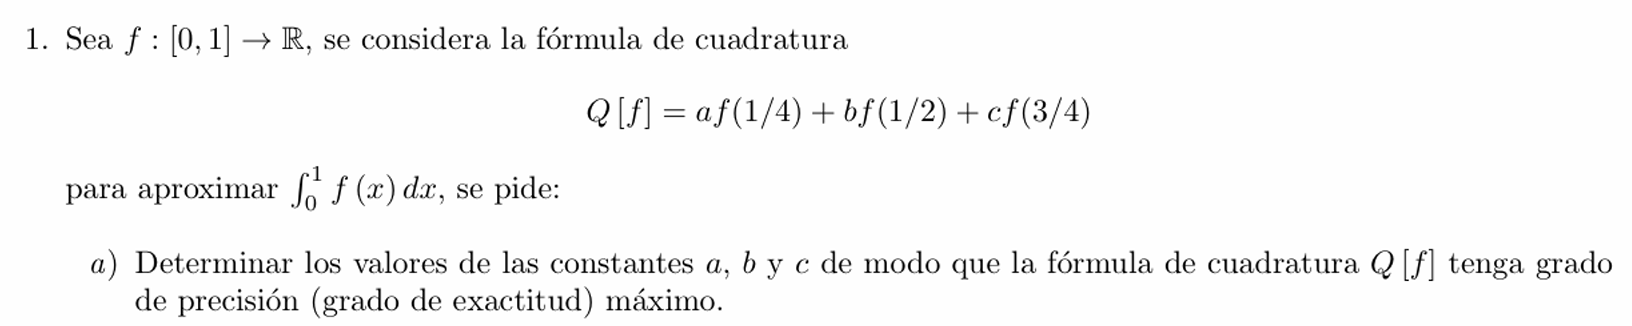

%Resolución sistema para sacar los wi
% 1 = a + b + c
% 1/2 = a*(1/2) + b + c*(3/2)
% 1/3 = a*(1/16) + b*(1/4) + c*(9/16)

 %resolvemos el sistema de ecuaciones (cuadratura exacta de 1 , x , x^2)

A=[1 1 1; 1/4 1/2 3/4; 1/16 1/4 9/16];

w1 =     0.6667
   -0.3333
    0.6667


b=[1; 1/2; 1/3];
wi= A\b;

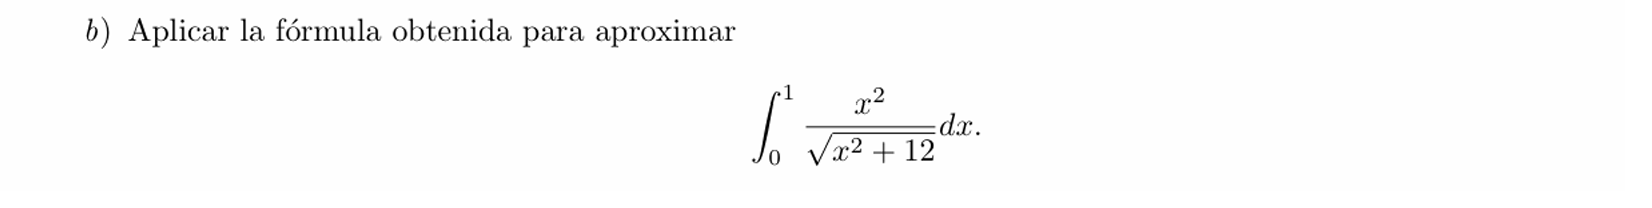

f = @(x) x.^2/sqrt(x.^2+12);

I = 0.0837


%Defino los nodos de la cuadratura
xi=[1/4 1/2 3/4];
Qf=sum(w*f(xi));

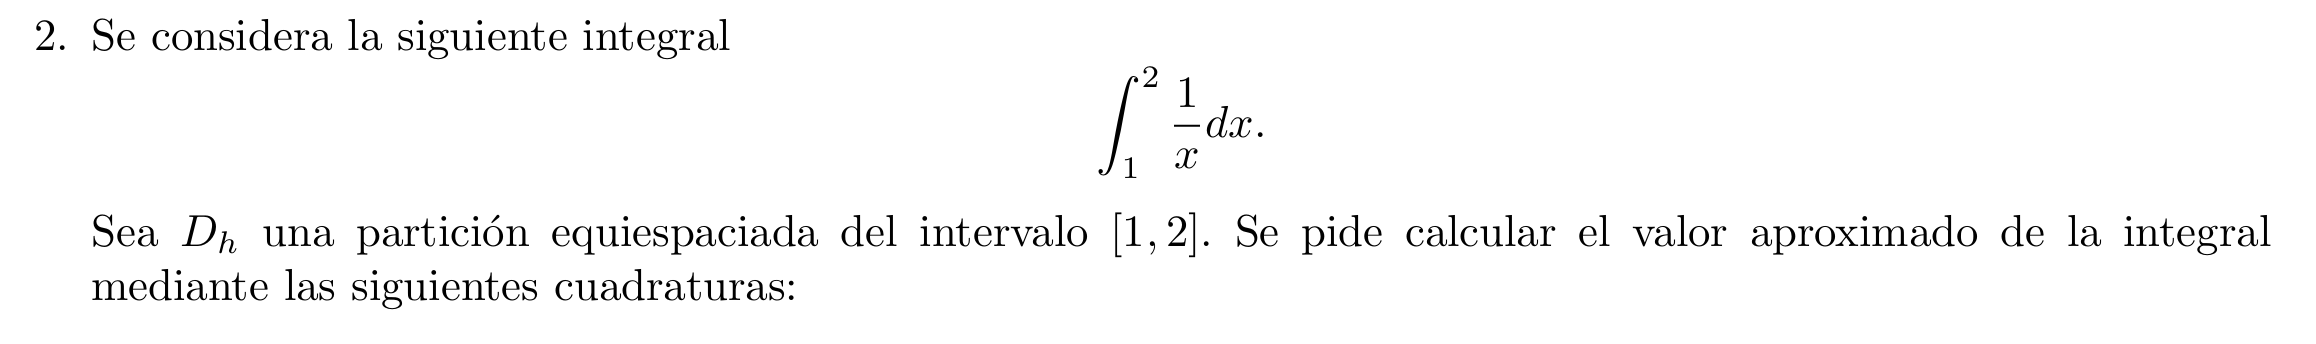

f=@(x) 1./x;

Ireal = 0.6931

ITC =     0.7500
    0.7083
    0.6970
    0.6941
    0.6934


ETC =     0.0569
    0.0152
    0.0039
    0.0010
    0.0002


a= 1;
b=2;
h= [0.5 0.25 0.175 0.0625];

Qf_trapecios=zeros(length(h),1);
Qf_simpsom = Qf_trapecios;
Qf_legendre4 = Qf_trapecios;
Qf_legendre8 = Qf_trapecios;


%Calculo el valor real de la integral para luego calcular el error
syms xsym

ISC =     0.5000
    0.6944
    0.6933
    0.6932
    0.6931


ESC =     0.1931
    0.0013
    0.0001
    0.0000
    0.0000


faux= 1./xsym;
Ireal=double(int(faux,xsym,a,b))

a) Regla de los** TRAPECIOS COMPUESTA:**

for k=1:length(h)
    n= (b-a)/h(k);
    sumf= 0;

    for i= 1:n-1
        x(i)= a+h(k)*i;
        sumf= sumf + f(x(i));
    end
    
    Qf_trapecios(k)= h(k)*0.5*(f(a) + 2*sumf + f(b));


IPMC =     0.6667
    0.6857
    0.6912
    0.6927
    0.6930


end

EPMC =     0.0265
    0.0074
    0.0019
    0.0005
    0.0001



Qf_trapecios


b)Regla de **SIMPSON COMPUESTA:**

for k=1:length(h)

IGL4 =     0.6931
    0.6931
    0.6931
    0.6931
    0.6931


EGL4 = 1.0e-06 *

    0.7631
    0.7631
    0.7631
    0.7631
    0.7631


    n= (b-a)/h(k);
    s1=0;
    s2=0;

    for i=1:n-1
        x=a +i*h(k);
    
        if rem(i,2)==0
           s2 = s2 + f(x);
        else
           s1 = s1 + f(x);
        end
    end
    
    Qf_simpsom(k) = h(k)/3 * (f(a) + 4*s1 + 2*s2 + f(b));

end

Qf_simpsom


c)Regla de **PUNTO MEDIO COMPUESTA**:

IPMC=zeros(d,1);
EPMC=zeros(d,1);

for i=1:d
    xi=a:h(i):b;
    xmidpoints=0.5*(xi(1:1:end-1)+xi(2:1:end));
    ymidpoints=f(xmidpoints);
    IPMC(i)=h(i)*sum(ymidpoints);
    EPMC(i)=abs(IPMC(i)-Ireal);
end

IPMC
EPMC

d) Cuadratura **COMPUESTA GAUSS-LEGENDRE n=4**

xi = [-0.8611363115940526 -0.3399810435848563 0.3399810435848563 0.8611363115940526];

IRT = 0.3643

ERT = 0.0410

wi = [0.3478548451374538 0.6521451548625461 0.6521451548625461 0.3478548451374538];

for k = 1:length(h)
    n = round((b - a) / h(k));  % Aseguramos que n sea un número entero
    zi = linspace(a, b, n+1); 
    Qf_legendre4(k) = 0;  

    for i = 1:n
        ai = zi(i);
        bi = zi(i+1);
        
        % Definimos la función g en el subintervalo [a_i, b_i] utilizando la transformación lineal
        g = @(x) 0.5*(bi - ai) * f(0.5*(bi - ai)*(x + 1) + ai);
        
        % Sumar el valor de la cuadratura de Gauss-Legendre en el subintervalo [a_i, b_i]
        Qf_legendre4(k) = Qf_legendre4(k) + sum(wi .* g(xi));
    end
end

Qf_legendre4


e)Cuadratura **COMPUESTA GAUSS-LEGENDRE n=8**

xi = [-0.9602898564975363 -0.7966664774136267 -0.5255324099163290 -0.1834346424956498 0.1834346424956498 0.5255324099163290 0.7966664774136267 0.9602898564975363];
wi = [0.1012285362903763 0.2223810344533745 0.3137066458778873 0.3626837833783620 0.3626837833783620 0.3137066458778873 0.2223810344533745 0.1012285362903763];

for k = 1:length(h)
    n = round((b - a) / h(k));  % Aseguramos que n sea un número entero
    zi = linspace(a, b, n+1); 
    Qf_legendre8(k) = 0;  

    for i = 1:n

IL1 = 0.4268

        ai = zi(i);

EL1 = 0.0215

        bi = zi(i+1);
        
        % Definimos la función g en el subintervalo [a_i, b_i] utilizando la transformación lineal
        g = @(x) 0.5*(bi - ai) * f(0.5*(bi - ai)*(x + 1) + ai);
        
        % Sumar el valor de la cuadratura de Gauss-Legendre en el subintervalo [a_i, b_i]
        Qf_legendre8(k) = Qf_legendre8(k) + sum(wi .* g(xi));
    end
end

Qf_legendre8


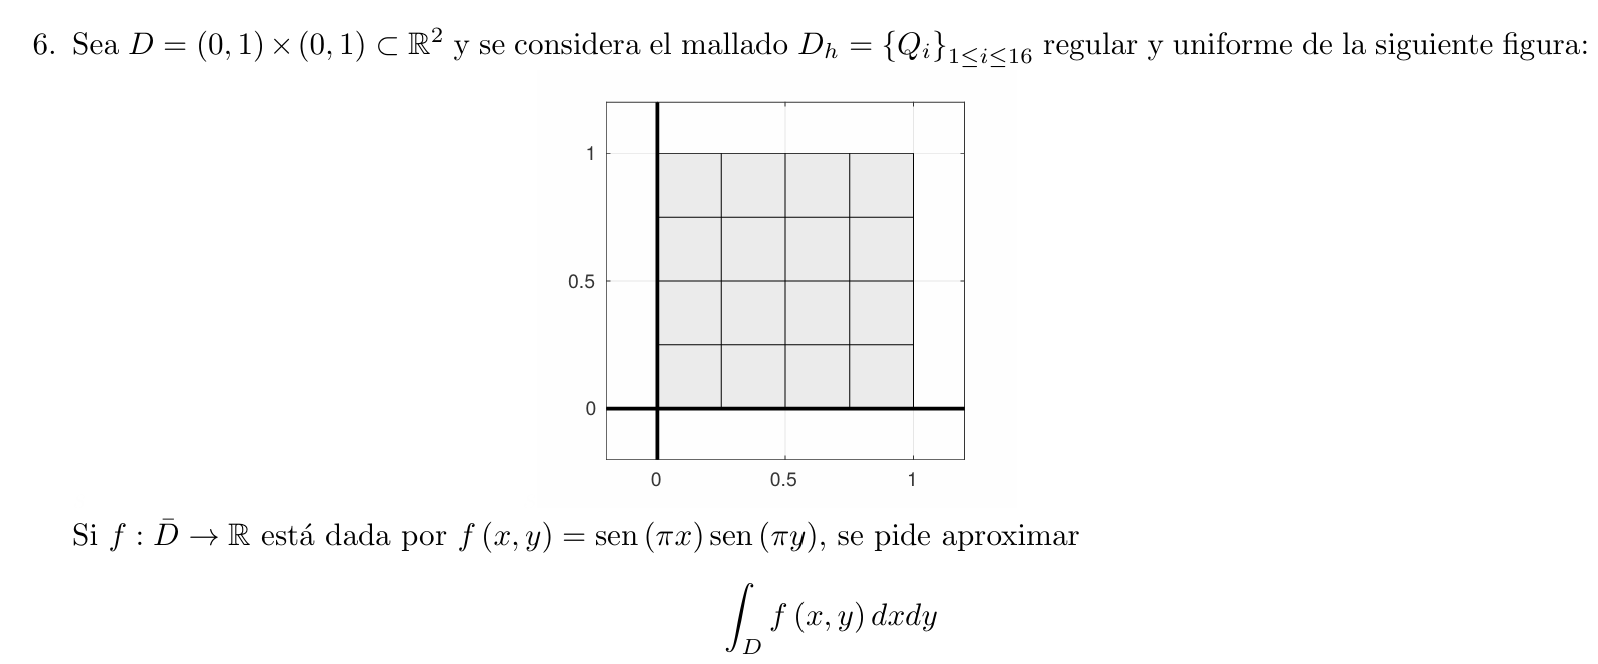

a) Utilizando **REGLA TRAPECIOS** en cada elemento del mallado:

Ireal=integral2(f,0,1,0,1);

Q = 50.3612

%creo el mallado y defino la función

f = @(x,y) sin(pi*x).*sin(pi*y);

% el malladao lo hago por cuadrados y meto los vértices a mano :(

   %     4           3



   %     1           2

Vx= [0 .25 .25 0; .25 .5 .5 .25; .5 .75 .75 .5; .75 1 1 .75;...
     0 .25 .25 0; .25 .5 .5 .25; .5 .75 .75 .5; .75 1 1 .75;...
     0 .25 .25 0; .25 .5 .5 .25; .5 .75 .75 .5; .75 1 1 .75;...
     0 .25 .25 0; .25 .5 .5 .25; .5 .75 .75 .5; .75 1 1 .75]; 

Vy= [0 0 .25 .25; .25 .25 .5 .5; .5 .5 .75 .75; .75 .75 1 1;...
     0 0 .25 .25; .25 .25 .5 .5; .5 .5 .75 .75; .75 .75 1 1;...
     0 0 .25 .25; .25 .25 .5 .5; .5 .5 .75 .75; .75 .75 1 1;...
     0 0 .25 .25; .25 .25 .5 .5; .5 .5 .75 .75; .75 .75 1 1]; 

%son matrices de 16x4 (16 cuadrados x 4 vértices cada uno)

% a)
Int = zeros(16,1);  %valor de la integral en cada elemento

for i=1:16
        % coordenadas del cuadrado que integro

        x1 = Vx(i,1); x2 = Vx(i,2);  hx=(x2 - x1) ;
        y1 = Vy(i,2); y2 = Vy(i,3);  hy=(y2 - y1) ;
        
        % Regla de los trapecios en 2D 
        Int(i) = hx*hy  / 4 * (f(x1, y1) + f(x1, y2) + f(x2, y1) + f(x2, y2) ); %hx*hy es el área de cada cuadrado
       
        
 end

 Q_trapecio= sum(Int)



b)  Utilizando **REGLA DE SIMPSON** en cada elemento del mallado:

%Aplico la regla del Simpson en 2D:
q=0;
for i=1:m
    for j=1:m
        x1=nx(i); x2=nx(i+1); x3=(nx(i)+nx(i+1))/2; y1=ny(j); y2=ny(j+1); y3=(ny(i)+ny(i+1))/2;
        q=q+(1/9)*(f(x1,y1)+f(x2,y2)+f(x2,y1)+f(x1,y2))+(4/9)*(f(x3,y1)+f(x2,y3)+f(x3,y2)+f(x1,y3))+(16/9)*f(x3,y3);
    end 
end 

Ireal=integral2(f,0,1,0,1);
IS=hx*hy*(1/4)*q;
ES=abs(IS-Ireal);

c) Utilizando **GAUSS LEGENDRE n=1** en cada elemento del mallado:

%Cuadratura de Gauss Legendre para n=1 un rectángulo [x1,x2]x[y1,y2] es Q=área(Qi)*f((x1+x2)/2, (y1+y2)/2))

%Datos:
hx=0.25;hy=0.25;ax=0;bx=1;ay=0;by=1;
f=@(x,y) sin(pi*x).*sin(pi*y); 

%Construyo el mallado:
nx = ax:hx:bx;
ny = ay:hy:by;
m=(bx-ax)/hx;

q=0;

for i=1:m
    for j=1:m
        x1=nx(i); x2=nx(i+1); y1=ny(j); y2=ny(j+1);
        q=q+f(0.5*(nx(i)+nx(i+1)), 0.5*(ny(j)+ny(j+1)));
    end 
end 
IL1=hx*hy*q
EL1=abs(IL1-Ireal)




% trapecios forma pau

%Aplico la regla del trapecio en 2D:

Q = 27.5430

q=0;
for i=1:m

masa = 0.0551

    for j=1:m
        x1=nx(i); x2=nx(i+1); y1=ny(j); y2=ny(j+1);
        q=q+f(x1,y1)+f(x2,y1)+f(x1,y2)+f(x2,y2); 
    end 
end 

Ireal=integral2(f,0,1,0,1);
IRT=hx*hy*(1/4)*q %Jacobiano si tenemos un cuadrilátero regular es hx*hy*(1/4)
ERT=abs(IRT-Ireal)

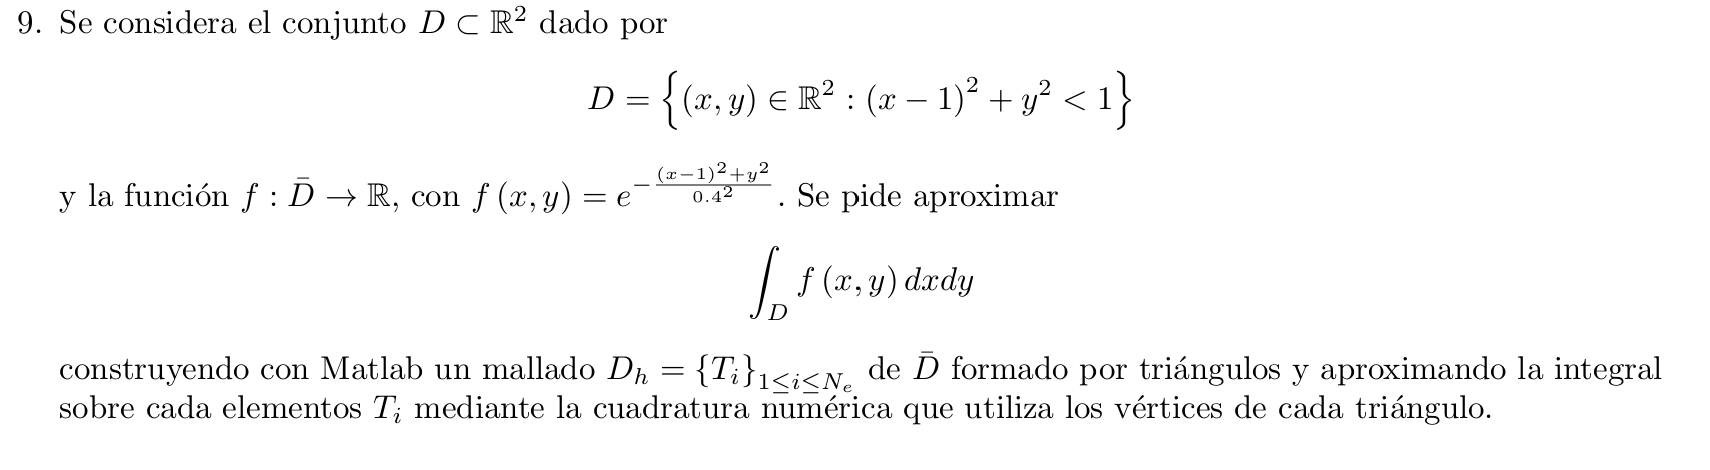

load('malla_ej9.mat')

f=@(x,y) exp(-((x-1).^2 +y.^2)/0.4^2);

xi=p(1,:);    %valor de la x de cada nodo
yi=p(2,:);    %valor de la y de cada nodo

elem=t(1:3,:)';    %guarda los nodos de cada triángulo

trisurf(elem,xi,yi,f(xi,yi)) %dibujo


Ne=length(elem);    %nos da elnúmero de triángulos que ha generado el mallado

Xg=[0 1 0;0 0 1];    %los valores de (xg,yg) que se usan para la cuadratura
wi=[1/6 1/6 1/6];    %pesos que se usan en la cuadratura

Q=0;

for i=1:Ne    %las coordenadas de cada nodo de cada triángulo
    X1=p(:,elem(i,1));
    X2=p(:,elem(i,2));
    X3=p(:,elem(i,3));

%ahora aplicamos la transformación afín para triángulos 
bi=X1;
Ai=[(X2-X1) (X3-X1)];

    for j=1:3
        X=bi+Ai*Xg(:,j); %creamos los tres vértices transformados 
        Q=Q+wi(j)*abs(det(Ai))*f(X(1), X(2));
     end 
end 
Q

## **EJS DE EXÁMENES DE OTROS AÑOS:**

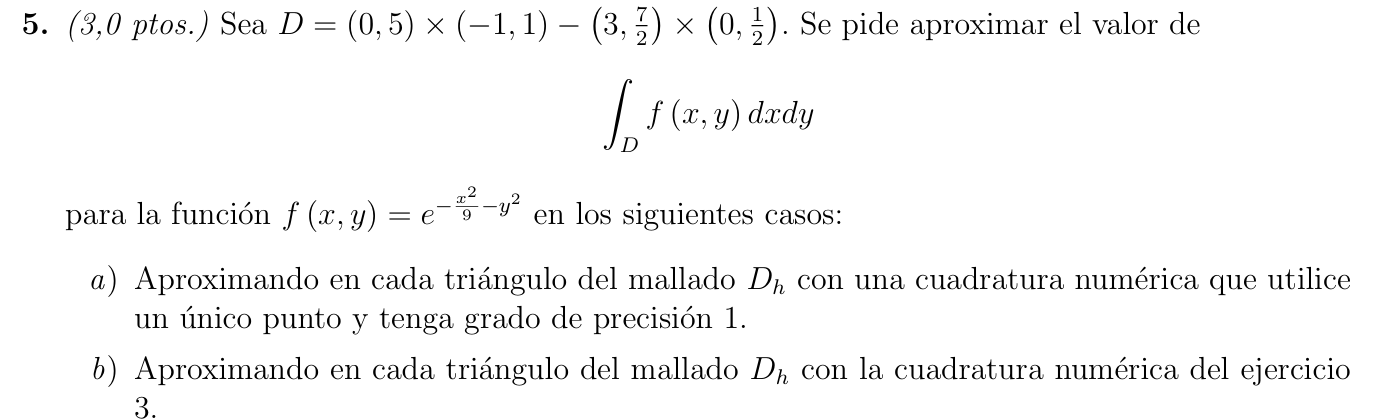

load("malladoej52023.mat", "p","e", "t") 

%APARTADO a)

f=@(x,y) exp(-x.^2/9-y.^2);
xi=p(1,:);
yi=p(2,:);
elem=t(1:3,:)'; %matriz que tiene en las tres primeras filas los nodos que forman el triángulo
Ne=length(elem); %Ne es el número de triángulos que tengo

w1=1/2; %peso para cuadratura de gauss legendre en triángulos de n=1
V1g=[1/3;1/3]; 

Qa=0;

for i=1:Ne
    %Sacamos los nodos del elemento i
    X1=p(:,elem(i,1));
    X2=p(:,elem(i,2));
    X3=p(:,elem(i,3));
    
    %Transfromación afín X=bi+Ai*X1g
    bi=X1;
    Ai=[(X2-X1) (X3-X1)]; 

    V1=bi+Ai*V1g;

    Qa= Qa+ abs(det(Ai))*(w1*f(V1(1),V1(2)));
end 

Qa

%APARTADO b)
Xg1=[0;0]; Xg2=[1;0]; Xg3=[0;1]; Xg4=[1/3;1/3];  
wb=[1/24 1/24 1/24 3/8];  

Qb=0;

for i=1:Ne
    %Sacamos los nodos del elemento i
    X1=p(:,elem(i,1));
    X2=p(:,elem(i,2));
    X3=p(:,elem(i,3));
    
    %Transfromación afín X=bi+Ai*X1g
    bi=X1;
    Ai=[(X2-X1) (X3-X1)]; 

    X1=bi+Ai*Xg1;
    X2=bi+Ai*Xg2;
    X3=bi+Ai*Xg3;
    X4=bi+Ai*Xg4;

    Qb= Qb+ abs(det(Ai))*(wb(1)*f(X1(1),X1(2))+wb(2)*f(X2(1),X2(2))+wb(3)*f(X3(1),X3(2))+wb(4)*f(X4(1),X4(2)));
end 

Qb

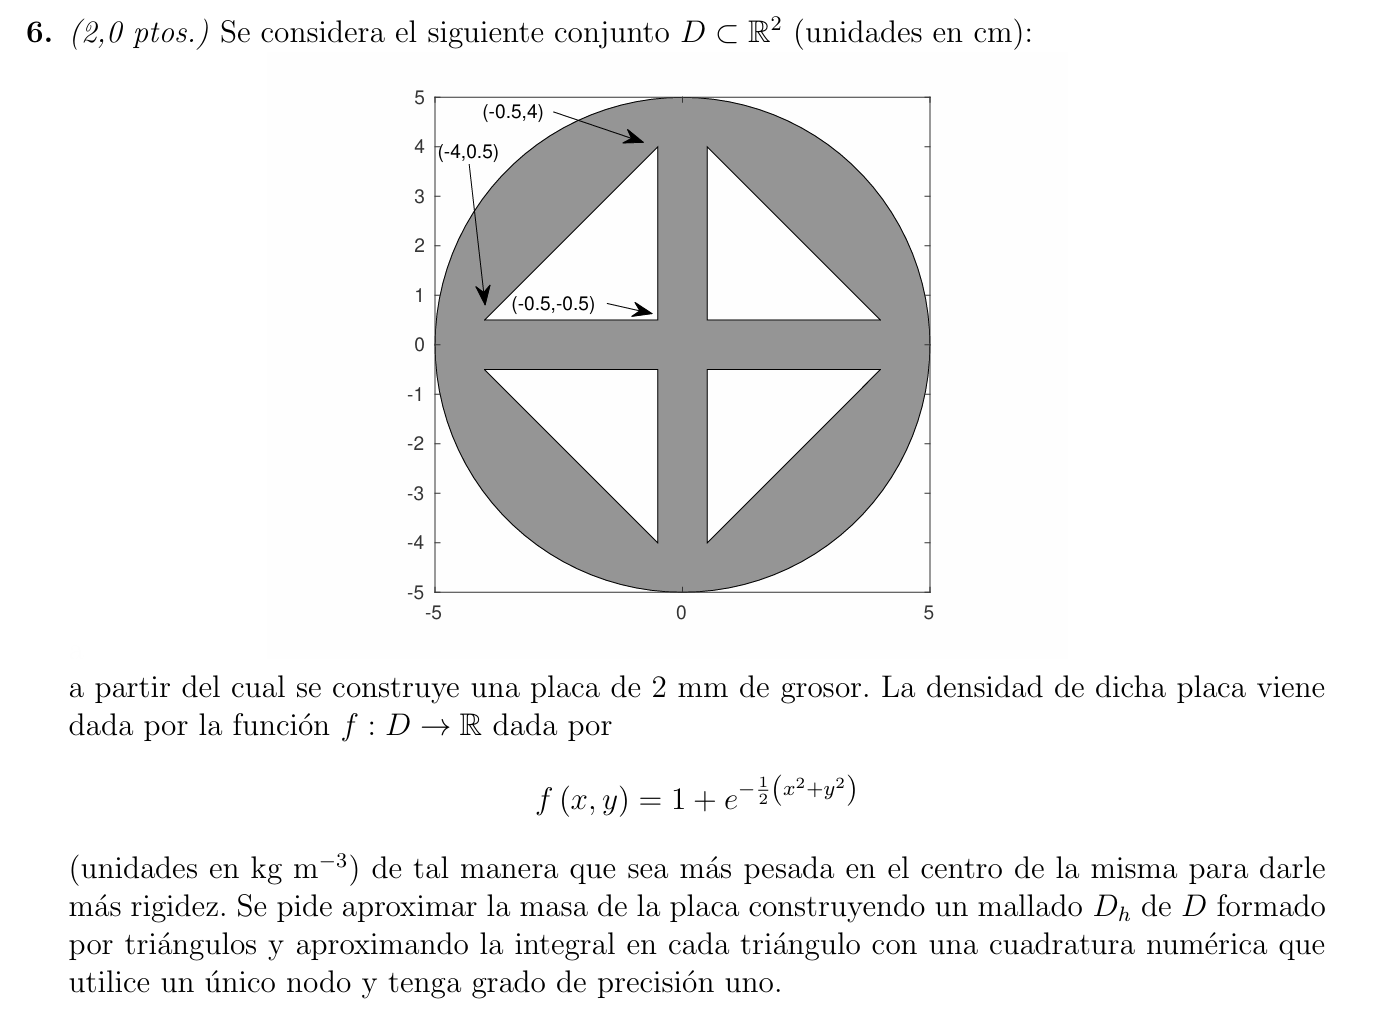

load("malladoej52022.mat", "p","e", "t") 

f=@(x,y) 1+exp(-0.5*(x.^2 + y.^2));

%load("malladoej52022.m", "p","e","t")
%load("malladoej52022.mat", 'p', 'e', 't')

xi=p(1,:);    %valor de la x de cada nodo
yi=p(2,:);    %valor de la y de cada nodo

elem=t(1:3,:)';    %guarda los nodos de cada triángulo

Ne=length(elem);    %nos da elnúmero de triángulos que ha generado el mallado

Xg=[1/3;1/3];    %los valores de (xg,yg) que se usan para la cuadratura
wi=[1/2];    %pesos que se usan en la cuadratura

Q=0;

for i=1:Ne    %las coordenadas de cada nodo de cada triángulo
    X1=p(:,elem(i,1));
    X2=p(:,elem(i,2));
    X3=p(:,elem(i,3));

%ahora aplicamos la transformación afín para triángulos 
bi=X1;
Ai=[(X2-X1) (X3-X1)];

   
        X=bi+Ai*Xg(:,1); %creamos los tres vértices transformados 
        Q=Q+wi(1)*abs(det(Ai))*f(X(1), X(2));
      
end 
Q

masa= Q*2/1000